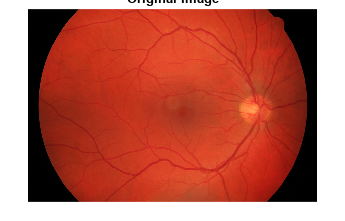

originalImage1=imread ('retina1.png');
greyImage1 = rgb2gray(originalImage1);
greyImage1 = double(greyImage1);
figure,imshow(originalImage1);title("Original Image");

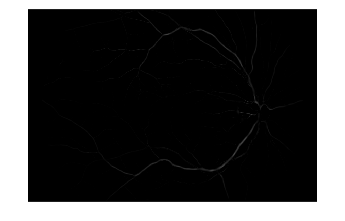

% Use a mask to remove the background
mask1 = find_mask(greyImage1);
mask1 = 1-mask1;
frangi1=FrangiFilter2D(greyImage1);
maskedFrangi1 = frangi1.*mask1;
figure; imshow(maskedFrangi1);

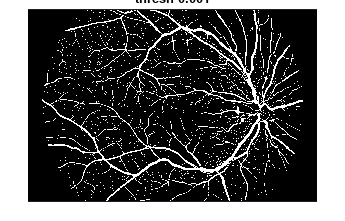

level = graythresh(maskedFrangi1);
thresholded1 = im2bw(maskedFrangi1,level*0.05);
thresholded = im2bw(maskedFrangi1,0.001);
figure; imshow(thresholded); title('thresh 0.001');

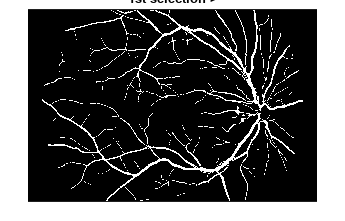

CC = bwconncomp(thresholded1, 8);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);
BW2 = ismember(L, find([S.Area] >= 30));
figure; imshow(BW2); title('1st selection >');

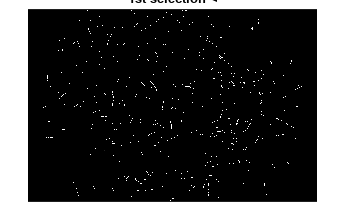

BW3 = ismember(L, find([S.Area] < 30)); 
figure; imshow(BW3); title('1st selection <');

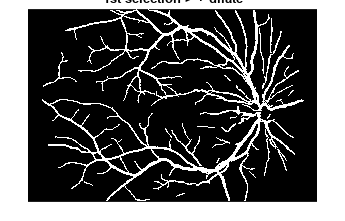

se4=strel('disk',1);
po=imdilate(BW2, se4);
figure; imshow(po); title('1st selection > + dilate')

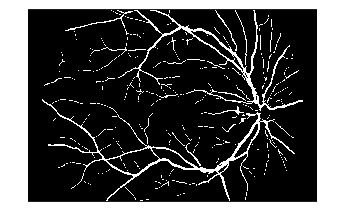

bw4 = imerode(po,se4);imshow(bw4);

Iskel = bwmorph(po,'skel',Inf);
Iendp = bwmorph(Iskel,'endpoints');
Iconn = bwlabel(Iskel,8);
Idiff = Iskel - Iendp;
Iendplab = Iconn - Idiff; %endpoints like connected components
[n,m] = size(bw4);

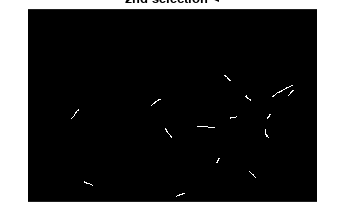

CC2 = bwconncomp(po, 4);
S2 = regionprops(CC2, 'Area');
L2 = labelmatrix(CC2);
po1 = ismember(L2, find([S2.Area] < 150));
figure; imshow(po1); title('2nd selection <');

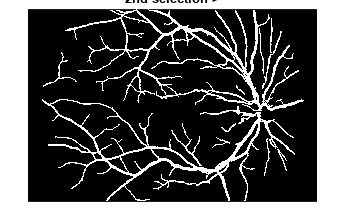

po2 = ismember(L2, find([S2.Area] >= 150));
figure; imshow(po2); title('2nd selection >');

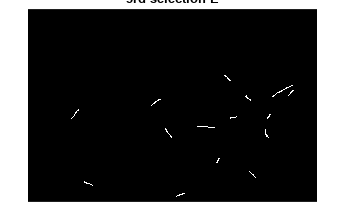

CC3 = bwconncomp(po1, 4);
S3 = regionprops(CC3, 'Area','Eccentricity');
L3 = labelmatrix(CC3);
po3 = ismember(L3, find([S3.Area] >= 200));
poCen = ismember(L3, find([S3.Eccentricity] >= 0.95));
figure; imshow(poCen); title('3rd selection E')

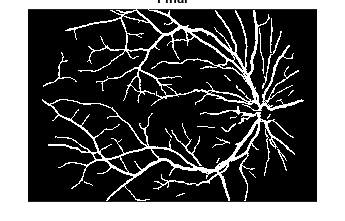

final = imadd(po2,poCen);
figure; imshow(final); title('Final')

function [outIm,whatScale,Direction] = FrangiFilter2D(I, options)
defaultoptions = struct('FrangiScaleRange', [1 5], 'FrangiScaleRatio', 2, 'FrangiBetaOne', 0.5, 'FrangiBetaTwo', 15, 'verbose',true,'BlackWhite',true);

% Process inputs
if(~exist('options','var'))
    options=defaultoptions; 
else
    tags = fieldnames(defaultoptions);
    for i=1:length(tags)
         if(~isfield(options,tags{i})),  options.(tags{i})=defaultoptions.(tags{i}); end
    end
    if(length(tags)~=length(fieldnames(options)))
        warning('FrangiFilter2D:unknownoption','unknown options found');
    end
end

sigmas=options.FrangiScaleRange(1):options.FrangiScaleRatio:options.FrangiScaleRange(2);
sigmas = sort(sigmas, 'ascend');

beta  = 2*options.FrangiBetaOne^2;
c     = 2*options.FrangiBetaTwo^2;

% Make matrices to store all filterd images
ALLfiltered=zeros([size(I) length(sigmas)]);
ALLangles=zeros([size(I) length(sigmas)]);

% Frangi filter for all sigmas
for i = 1:length(sigmas)
    % Make 2D hessian
    [Dxx,Dxy,Dyy] = Hessian2D(I,sigmas(i));
    
    % Correct for scale
    Dxx = (sigmas(i)^2)*Dxx;
    Dxy = (sigmas(i)^2)*Dxy;
    Dyy = (sigmas(i)^2)*Dyy;
   
    % Calculate (abs sorted) eigenvalues and vectors
    [Lambda2,Lambda1,Ix,Iy]=eig2image(Dxx,Dxy,Dyy);

    % Compute the direction of the minor eigenvector
    angles = atan2(Ix,Iy);

    % Compute some similarity measures
    Lambda1(Lambda1==0) = eps;
    Rb = (Lambda2./Lambda1).^2;
    S2 = Lambda1.^2 + Lambda2.^2;
   
    % Compute the output image
    Ifiltered = exp(-Rb/beta) .*(ones(size(I))-exp(-S2/c));
    
    % see pp. 45
    if(options.BlackWhite)
        Ifiltered(Lambda1<0)=0;
    else
        Ifiltered(Lambda1>0)=0;
    end
    % store the results in 3D matrices
    ALLfiltered(:,:,i) = Ifiltered;
    ALLangles(:,:,i) = angles;
end

% Return for every pixel the value of the scale(sigma) with the maximum 
% output pixel value
if length(sigmas) > 1
    [outIm,whatScale] = max(ALLfiltered,[],3);
    outIm = reshape(outIm,size(I));
    if(nargout>1)
        whatScale = reshape(whatScale,size(I));
    end
    if(nargout>2)
        Direction = reshape(ALLangles((1:numel(I))'+(whatScale(:)-1)*numel(I)),size(I));
    end
else
    outIm = reshape(ALLfiltered,size(I));
    if(nargout>1)
            whatScale = ones(size(I));
    end
    if(nargout>2)
        Direction = reshape(ALLangles,size(I));
    end
end

function [Dxx,Dxy,Dyy] = Hessian2D(I,Sigma)
if nargin < 2, Sigma = 1; end

% Make kernel coordinates
[X,Y]   = ndgrid(-round(3*Sigma):round(3*Sigma));

% Build the gaussian 2nd derivatives filters
DGaussxx = 1/(2*pi*Sigma^4) * (X.^2/Sigma^2 - 1) .* exp(-(X.^2 + Y.^2)/(2*Sigma^2));
DGaussxy = 1/(2*pi*Sigma^6) * (X .* Y)           .* exp(-(X.^2 + Y.^2)/(2*Sigma^2));
DGaussyy = DGaussxx';

Dxx = imfilter(I,DGaussxx,'conv');
Dxy = imfilter(I,DGaussxy,'conv');
Dyy = imfilter(I,DGaussyy,'conv');
end
end

function [Lambda1,Lambda2,Ix,Iy]=eig2image(Dxx,Dxy,Dyy)

% Compute the eigenvectors of J, v1 and v2
tmp = sqrt((Dxx - Dyy).^2 + 4*Dxy.^2);
v2x = 2*Dxy; v2y = Dyy - Dxx + tmp;

% Normalize
mag = sqrt(v2x.^2 + v2y.^2); i = (mag ~= 0);
v2x(i) = v2x(i)./mag(i);
v2y(i) = v2y(i)./mag(i);

% The eigenvectors are orthogonal
v1x = -v2y; 
v1y = v2x;

% Compute the eigenvalues
mu1 = 0.5*(Dxx + Dyy + tmp);
mu2 = 0.5*(Dxx + Dyy - tmp);

% Sort eigen values by absolute value abs(Lambda1)<abs(Lambda2)
check=abs(mu1)>abs(mu2);

Lambda1=mu1; Lambda1(check)=mu2(check);
Lambda2=mu2; Lambda2(check)=mu1(check);

Ix=v1x; Ix(check)=v2x(check);
Iy=v1y; Iy(check)=v2y(check);
end

function [Mask] = find_mask(I)
  %   A function finding the mask for retinal images
  % 1=Masked points
  % 0=Signal points

  if max(I)<=1
      I = I*255;
  end

  Black = I<10;
  White = I>245;
  Mask  = Black | White;
  
  se = strel('disk',1);
  
  % Action:
  for i=1:12
    Mask = imdilate(Mask,se);
  end
end

